% Data from [Mesh data structure selection for mesh generation 
%    and FEA applications]
% Memory storage
mem_element = [25 25 25 25 25 25 6 6 18 18 25 25]';
mem_connect = [143 93 129 119 142 128 43 77 115 129 200 250]';
mem_total = mem_element + mem_connect;

% Operation count
% F(R) E(R) V (R) R(F) E(F) V (F) R(E) F(E) V (E) R(V ) F(V ) E(V )
%4 36 30 2 3 13 50 5 2 619 399 14

ope = [4 36 30 2 3 13 50 5 2 619 399 14
    4 36 30 211 3 13 512 877 2 23 1394 1749
    4 36 30 2 3 13 297 252 2 360 35 840
    4 36 30 48 3 13 5 210 2 339 1710 14
    4 36 30 211 3 13 512 252 2 23 35 14
    4 36 30 211 3 13 512 252 2 23 35 840
    72 58 4 302 24 3 214 721 2 23 3462 1969
    84 58 4 2 24 3 214 731 2 23 3532 84
    4 58 21 2 24 3 267 251 2 360 35 1449
    4 58 21 2 24 3 267 251 2 360 35 84
    4 36 2 2 3 2 50 5 2 3 399 14
    1 1 1 1 1 1 1 1 1 1 1 1];
%ope(ope<5) = 1;

% DSC references
    name_ref = ['F(T)'; 'E(T)'; 'V(T)'; 'T(F)'; 'E(F)'; ...
        'V(F)'; 'T(E)'; 'F(E)'; 'V(E)'; 'T(V)'; 'F(V)'; 'E(V)'];
dsc_ref = [2880 48 1302 596 2586 2600 15 261 8122 115 48 323]';

% Their reference
mega_ref = [73 23 429 543 8121 185 1 950 12006 27 48 2102]';


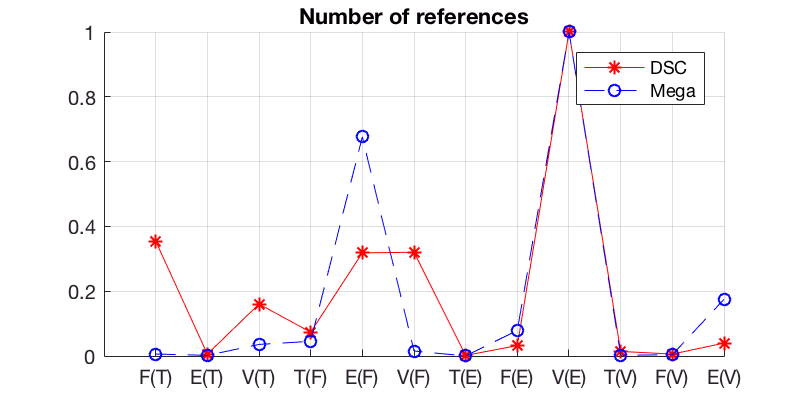

t = table((name_ref), dsc_ref, mega_ref, ...
    'VariableNames',{'Refs' 'DSC' 'Mega'});

hh1=figure; hold on;
plot(dsc_ref/max(dsc_ref), 'r*-');
plot(mega_ref/max(mega_ref), 'bo--');

title('Number of references');legend('DSC', 'Mega');
ax = gca;ax.XTickLabel = name_ref;tt=1:12; ax.XTick=tt;
set(hh1, 'Position', [100, 100, 400, 200]);
hold off;
grid on;

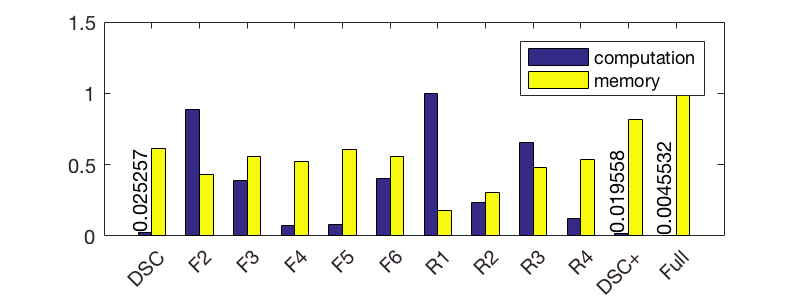

% Computation
% average operation
ope_total = ope * mega_ref;

ope_total_scale = ope_total / max(ope_total);
mem_total_scale = mem_total / max(mem_total);
name_method = {'1.F1, one level, DSC', '2.F2 circular tet-node', ...
    '3.F3, cicular faces-vertices', '4.F4, circular tet-edge', ...
    '5.F5, 2 circualr', '6.F6, reduce 2 circular'...
    '7.R1, compact', '8.R2, flex', '9.R3, mid', '10.R4, mid flex', 'dsc opt', 'full'};

hh2 = figure;
bar([ope_total_scale mem_total_scale], 'BarWidth',1.0);

set(gca,'xticklabel', {'DSC'; 'F2'; ...
    'F3'; 'F4'; 'F5'; 'F6'; 'R1'; 'R2'; 'R3'; 'R4'; 'DSC+'; 'Full'});
ax = gca; ax.XTickLabelRotation=45;
% title('Memory and computation');
% xlim([0, 1.2]);
 ylim([0, 1.5]); xlim([0, length(name_method)+1]);
 set(hh2, 'Position', [100, 100, 400, 150]);
 legend({'computation'; 'memory'});
 
 text(1, ope_total_scale(1), num2str(ope_total_scale(1)), ...
     'HorizontalAlignment','left',...
               'VerticalAlignment','bottom', 'rotation', 90);
text(11, ope_total_scale(11), num2str(ope_total_scale(11)), ...
     'HorizontalAlignment','left',...
               'VerticalAlignment','bottom', 'rotation', 90);
text(12, ope_total_scale(12), num2str(ope_total_scale(12)), ...
     'HorizontalAlignment','left',...
               'VerticalAlignment','bottom', 'rotation', 90);


index = 1:length(name_method);
disp(table(index', name_method', ope_total/1000, 'VariableNames', {'index' 'Method' 'ope_aver_e3'}));

    index                Method                ope_aver_e3
    _____    ______________________________    ___________
     1       '1.F1, one level, DSC'            135.95     
     2       '2.F2 circular tet-node'          4756.9     
     3       '3.F3, cicular faces-vertices'    2082.6     
     4       '4.F4, circular tet-edge'            411     
     5       '5.F5, 2 circualr'                450.98     
     6       '6.F6, reduce 2 circular'         2187.2     
     7       '7.R1, compact'                   5382.6     
     8       '8.R2, flex'                      1271.1     
     9       '9.R3, mid'                       3527.1     
    10       '10.R4, mid flex'                 657.88     
    11       'dsc opt'                         105.27     
    12       'full'                            24.508     


% DSC operation cost
index = 1:12;
disp('DSC information');

DSC information


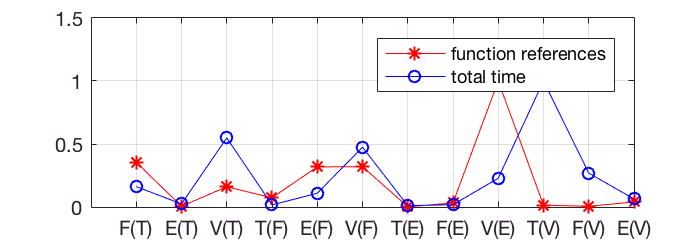



hh2 = figure;
dsc_ref_scale = dsc_ref/max(dsc_ref);
plot(dsc_ref_scale, 'r*-'); hold on;

ope1_t = ope(1,:) / max(ope(1,:));
total_time = dsc_ref_scale'.*ope1_t;
total_time = total_time / max(total_time);
plot(total_time, 'bo-');

ax = gca;ax.XTickLabel = name_ref;tt=1:12; ax.XTick=tt;
grid on;
hold off;
ylim([0 1.5]);
legend('function references', 'total time');
set(hh2, 'Position', [100, 100, 350, 120]);


% figure;
% ope_t = ope(1,:) / max(ope(1,:));
% dsc_time = dsc_ref_scale'.*ope_t;
% plot(dsc_time);

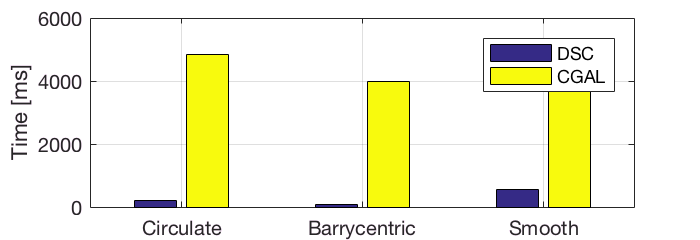

% Cells complex

dsc_c = [214 91 563];
cgal_c = [4843 3996 4758];
name = {'Circulate' 'Barrycentric' 'Smooth'};

hh3 = figure;
bar([dsc_c' cgal_c']);
set(hh3, 'Position', [100, 100, 350, 120]);
legend('DSC', 'CGAL'); grid on;
set(gca,'xticklabel', name);
ylabel('Time [ms]');